# Two Parallel Charged Plates

% The variables
syms d v r real positive;
assume(d>0)
assume(r>0)
assume(v>0)


## The vectors

R = (d^2+r^2)^(1/2)

$$R = \sqrt{d^{2}+r^{2}}$$

vec_l = [d,r,0]/R  % speed of light from left plate 

$$vec\_l = \left(\begin{array}{ccc} \frac{d}{\sqrt{d^{2}+r^{2}}} & \frac{r}{\sqrt{d^{2}+r^{2}}} & 0 \end{array}\right)$$

vec_r = [-d,r,0]/R  % speed of light vector from right plate

$$vec\_r = \left(\begin{array}{ccc} -\frac{d}{\sqrt{d^{2}+r^{2}}} & \frac{r}{\sqrt{d^{2}+r^{2}}} & 0 \end{array}\right)$$

r_vec_l = (vec_l - [v,0,0]) % relative speed of left force particle (v in light speed fraction =v/c)

$$r\_vec\_l = \left(\begin{array}{ccc} \frac{d}{\sqrt{d^{2}+r^{2}}}-v & \frac{r}{\sqrt{d^{2}+r^{2}}} & 0 \end{array}\right)$$

r_vec_r = (vec_r - [v,0,0]) % relative speed of right force particle

$$r\_vec\_r = \left(\begin{array}{ccc} -v-\frac{d}{\sqrt{d^{2}+r^{2}}} & \frac{r}{\sqrt{d^{2}+r^{2}}} & 0 \end{array}\right)$$


dprd_l = simplifyFraction(dot(vec_l,r_vec_l)^2/dot(r_vec_l,r_vec_l)) % Cosine^2 

$$dprd\_l = \frac{{\left(d^{2}+r^{2}-d\,v\,\sqrt{d^{2}+r^{2}}\right)}^{2}}{\left(d^{2}+r^{2}\right)\,\left(v^{2}\,\left(d^{2}+r^{2}\right)+d^{2}+r^{2}-2\,d\,v\,\sqrt{d^{2}+r^{2}}\right)}$$


dprd_r = simplifyFraction(dot(vec_r,r_vec_r)^2/dot(r_vec_r,r_vec_r)) % Cosine^2 

$$dprd\_r = \frac{{\left(d^{2}+r^{2}+d\,v\,\sqrt{d^{2}+r^{2}}\right)}^{2}}{\left(d^{2}+r^{2}\right)\,\left(v^{2}\,\left(d^{2}+r^{2}\right)+d^{2}+r^{2}+2\,d\,v\,\sqrt{d^{2}+r^{2}}\right)}$$


tdotp = simplify(expand(dprd_l + dprd_r),'Steps',100)

$$tdotp = 2-\frac{2\,r^{2}\,v^{2}\,\left(v^{2}+1\right)}{2\,r^{2}\,v^{2}+r^{2}\,v^{4}+d^{2}\,\left(v^{4}-2\,v^{2}+1\right)+r^{2}}$$

## The force


dforce = r*d*tdotp/R^3 % Force in the x direction

$$dforce = -\frac{d\,r\,\left(\frac{2\,r^{2}\,v^{2}\,\left(v^{2}+1\right)}{2\,r^{2}\,v^{2}+r^{2}\,v^{4}+d^{2}\,\left(v^{4}-2\,v^{2}+1\right)+r^{2}}-2\right)}{{\left(d^{2}+r^{2}\right)}^{3/2}}$$

dforce = simplify(expand(dforce),'Steps',100)

$$dforce = \frac{2\,d^{3}\,r\,v^{4}-4\,d^{3}\,r\,v^{2}+2\,d^{3}\,r+2\,d\,r^{3}\,v^{2}+2\,d\,r^{3}}{\left(\left(v^{4}-2\,v^{2}+1\right)\,d^{2}+\left(v^{4}+2\,v^{2}+1\right)\,r^{2}\right)\,{\left(d^{2}+r^{2}\right)}^{3/2}}$$

## Check at v = 0

v=0;
df_v_zero = simplify(subs(dforce),'Steps',100)

$$df\_v\_zero = \frac{2\,d\,r}{{\left(d^{2}+r^{2}\right)}^{3/2}}$$

## Continue use taylor expansion arround small values of v

syms d v r real positive;
dfroce_v = simplify(taylor(dforce,v,ExpansionPoint=0,Order=8),'Steps',100)

$$dfroce\_v = -\frac{2\,d\,r\,\left(-d^{6}+5\,d^{4}\,r^{2}\,v^{6}+3\,d^{4}\,r^{2}\,v^{4}+d^{4}\,r^{2}\,v^{2}-3\,d^{4}\,r^{2}-10\,d^{2}\,r^{4}\,v^{6}+2\,d^{2}\,r^{4}\,v^{4}+2\,d^{2}\,r^{4}\,v^{2}-3\,d^{2}\,r^{4}+r^{6}\,v^{6}-r^{6}\,v^{4}+r^{6}\,v^{2}-r^{6}\right)}{{\left(d^{2}+r^{2}\right)}^{9/2}}$$

totf = simplify(int(dfroce_v,r),'Steps',100)

$$totf = -\frac{2\,d\,\left(2\,d^{6}\,v^{6}+14\,d^{6}\,v^{4}-70\,d^{6}\,v^{2}+105\,d^{6}+7\,d^{4}\,r^{2}\,v^{6}+49\,d^{4}\,r^{2}\,v^{4}-245\,d^{4}\,r^{2}\,v^{2}+315\,d^{4}\,r^{2}+140\,d^{2}\,r^{4}\,v^{6}+140\,d^{2}\,r^{4}\,v^{4}-280\,d^{2}\,r^{4}\,v^{2}+315\,d^{2}\,r^{4}-105\,r^{6}\,v^{6}+105\,r^{6}\,v^{4}-105\,r^{6}\,v^{2}+105\,r^{6}\right)}{105\,{\left(d^{2}+r^{2}\right)}^{7/2}}$$



totfO4 = simplify(taylor(totf,v,ExpansionPoint=0,Order=4),'Steps',100)

$$totfO4 = \frac{2\,d\,\left(2\,d^{2}\,v^{2}-3\,d^{2}+3\,r^{2}\,v^{2}-3\,r^{2}\right)}{3\,{\left(d^{2}+r^{2}\right)}^{3/2}}$$

totfO4at0 = totfO4

$$totfO4at0 = \frac{2\,d\,\left(2\,d^{2}\,v^{2}-3\,d^{2}+3\,r^{2}\,v^{2}-3\,r^{2}\right)}{3\,{\left(d^{2}+r^{2}\right)}^{3/2}}$$

r=0;
totfO4at0 = subs(totfO4at0)

$$totfO4at0 = -\frac{2\,\left(3\,d^{2}-2\,d^{2}\,v^{2}\right)}{3\,d^{2}}$$

syms d v r c real
assume(d>0)
assume(r>0)
assume(c>0)
totfO4at0 = simplify(subs(totfO4at0))

$$totfO4at0 = \frac{4\,v^{2}}{3}-2$$

totAtR = simplify(totfO4 - totfO4at0,'Steps',100)

$$totAtR = \frac{2\,d\,\left(2\,d^{2}\,v^{2}-3\,d^{2}+3\,r^{2}\,v^{2}-3\,r^{2}\right)}{3\,{\left(d^{2}+r^{2}\right)}^{3/2}}-\frac{4\,v^{2}}{3}+2$$

## Check the equation


v=0;
fv_zero = simplify(subs(totAtR),'Steps',100)

$$fv\_zero = 2-\frac{2\,d}{\sqrt{d^{2}+r^{2}}}$$

syms d v r real positive;
assume(d>0)
assume(r>0)
assume(c>0)
assume(v>0)
ratiof = simplify(totAtR/fv_zero,'Steps',100)

$$ratiof = 1-\frac{d\,r^{2}\,v^{2}}{3\,\left(d\,r^{2}-{\left(d^{2}+r^{2}\right)}^{3/2}+d^{3}\right)}-\frac{2\,v^{2}}{3}$$

## Plots


ratiofp =  ratiof;
r=100;
d=0.1;
ratiofp = simplify(subs(ratiofp))

$$ratiofp = \frac{\sqrt{1000001}\,v^{2}}{3000003}-\frac{666667\,v^{2}}{1000001}+1$$

plotrange = [0,0.99];
fplot(ratiofp,plotrange)
hold on
relEq = sqrt(1-v^2)

$$relEq = \sqrt{1-v^{2}}$$

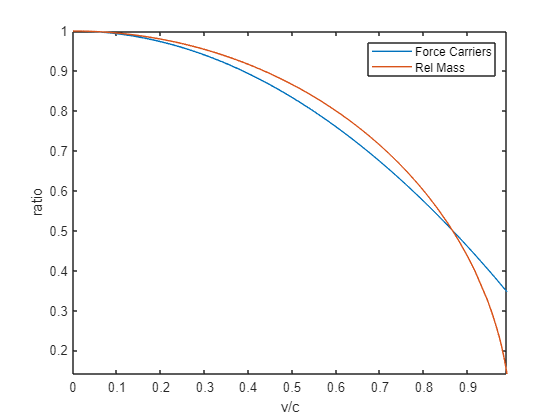

fplot(relEq,plotrange)
xlabel('v/c') 
ylabel('ratio') 
legend({'Force Carriers',"Rel Mass"},'Location','northeast')
hold off

syms d v r real positive;
assume(d>0)
assume(r>0)
assume(v>0)

## No Taylor


totf = simplify(simplifyFraction(int(expand(dforce),r)),'Steps',100)

$$totf = \begin{array}{l} \frac{v\,\left(\frac{d^{2}\,\sigma_{17}}{2}-\frac{d^{2}\,\sigma_{14}}{4}-\frac{d^{2}\,\sigma_{13}}{4}-\frac{r^{2}\,\sigma_{14}}{4}-\frac{r^{2}\,\sigma_{13}}{4}+\frac{d^{2}\,\sigma_{16}}{4}+\frac{d^{2}\,\sigma_{15}}{4}+\frac{r^{2}\,\sigma_{16}}{4}+\frac{r^{2}\,\sigma_{15}}{4}-\frac{\sigma_{1}}{2}+\frac{r^{2}\,\sigma_{17}}{2}\right)}{\sigma_{19}}-\frac{\frac{3\,\sigma_{1}}{4}-\sigma_{7}-\sigma_{6}-\sigma_{3}-\sigma_{2}+\sigma_{9}+\sigma_{8}+\sigma_{5}+\sigma_{4}+\sigma_{11}+\sigma_{10}}{v\,\sigma_{19}}-\frac{v^{3}\,\left(\sigma_{11}-\sigma_{7}-\sigma_{6}-\sigma_{3}-\sigma_{2}+\sigma_{9}+\sigma_{8}+\sigma_{5}+\sigma_{4}-\frac{\sigma_{1}}{4}+\sigma_{10}\right)}{\sigma_{19}}\\ \mathrm{where}\\ \sigma_{1}=\sqrt{\frac{4\,d^{4}\,v^{2}}{\sigma_{12}}+\frac{4\,d^{2}\,r^{2}\,v^{2}}{\sigma_{12}}}\\ \sigma_{2}=\frac{r^{2}\,\sigma_{13}}{8}\\ \sigma_{3}=\frac{r^{2}\,\sigma_{14}}{8}\\ \sigma_{4}=\frac{r^{2}\,\sigma_{15}}{8}\\ \sigma_{5}=\frac{r^{2}\,\sigma_{16}}{8}\\ \sigma_{6}=\frac{d^{2}\,\sigma_{13}}{8}\\ \sigma_{7}=\frac{d^{2}\,\sigma_{14}}{8}\\ \sigma_{8}=\frac{d^{2}\,\sigma_{15}}{8}\\ \sigma_{9}=\frac{d^{2}\,\sigma_{16}}{8}\\ \sigma_{10}=\frac{r^{2}\,\sigma_{17}}{4}\\ \sigma_{11}=\frac{d^{2}\,\sigma_{17}}{4}\\ \sigma_{12}=v^{4}+2\,v^{2}+1\\ \sigma_{13}=\log\left(r+r\,v^{2}+d\,\mathrm{i}-\sigma_{18}\right)\\ \sigma_{14}=\log\left(r+r\,v^{2}-d\,\mathrm{i}+\sigma_{18}\right)\\ \sigma_{15}=\log\left(d+r\,\mathrm{i}+2\,v\,\sqrt{\sigma_{19}}+d\,v^{2}-\sigma_{20}\right)\\ \sigma_{16}=\log\left(d-r\,\mathrm{i}+2\,v\,\sqrt{\sigma_{19}}+d\,v^{2}+\sigma_{20}\right)\\ \sigma_{17}=\log\left(v^{2}+1\right)\\ \sigma_{18}=d\,v^{2}\,\mathrm{i}\\ \sigma_{19}=d^{2}+r^{2}\\ \sigma_{20}=r\,v^{2}\,\mathrm{i} \end{array}$$

totfat0 = totf

$$totfat0 = \begin{array}{l} \frac{v\,\left(\frac{d^{2}\,\sigma_{17}}{2}-\frac{d^{2}\,\sigma_{14}}{4}-\frac{d^{2}\,\sigma_{13}}{4}-\frac{r^{2}\,\sigma_{14}}{4}-\frac{r^{2}\,\sigma_{13}}{4}+\frac{d^{2}\,\sigma_{16}}{4}+\frac{d^{2}\,\sigma_{15}}{4}+\frac{r^{2}\,\sigma_{16}}{4}+\frac{r^{2}\,\sigma_{15}}{4}-\frac{\sigma_{1}}{2}+\frac{r^{2}\,\sigma_{17}}{2}\right)}{\sigma_{19}}-\frac{\frac{3\,\sigma_{1}}{4}-\sigma_{7}-\sigma_{6}-\sigma_{3}-\sigma_{2}+\sigma_{9}+\sigma_{8}+\sigma_{5}+\sigma_{4}+\sigma_{11}+\sigma_{10}}{v\,\sigma_{19}}-\frac{v^{3}\,\left(\sigma_{11}-\sigma_{7}-\sigma_{6}-\sigma_{3}-\sigma_{2}+\sigma_{9}+\sigma_{8}+\sigma_{5}+\sigma_{4}-\frac{\sigma_{1}}{4}+\sigma_{10}\right)}{\sigma_{19}}\\ \mathrm{where}\\ \sigma_{1}=\sqrt{\frac{4\,d^{4}\,v^{2}}{\sigma_{12}}+\frac{4\,d^{2}\,r^{2}\,v^{2}}{\sigma_{12}}}\\ \sigma_{2}=\frac{r^{2}\,\sigma_{13}}{8}\\ \sigma_{3}=\frac{r^{2}\,\sigma_{14}}{8}\\ \sigma_{4}=\frac{r^{2}\,\sigma_{15}}{8}\\ \sigma_{5}=\frac{r^{2}\,\sigma_{16}}{8}\\ \sigma_{6}=\frac{d^{2}\,\sigma_{13}}{8}\\ \sigma_{7}=\frac{d^{2}\,\sigma_{14}}{8}\\ \sigma_{8}=\frac{d^{2}\,\sigma_{15}}{8}\\ \sigma_{9}=\frac{d^{2}\,\sigma_{16}}{8}\\ \sigma_{10}=\frac{r^{2}\,\sigma_{17}}{4}\\ \sigma_{11}=\frac{d^{2}\,\sigma_{17}}{4}\\ \sigma_{12}=v^{4}+2\,v^{2}+1\\ \sigma_{13}=\log\left(r+r\,v^{2}+d\,\mathrm{i}-\sigma_{18}\right)\\ \sigma_{14}=\log\left(r+r\,v^{2}-d\,\mathrm{i}+\sigma_{18}\right)\\ \sigma_{15}=\log\left(d+r\,\mathrm{i}+2\,v\,\sqrt{\sigma_{19}}+d\,v^{2}-\sigma_{20}\right)\\ \sigma_{16}=\log\left(d-r\,\mathrm{i}+2\,v\,\sqrt{\sigma_{19}}+d\,v^{2}+\sigma_{20}\right)\\ \sigma_{17}=\log\left(v^{2}+1\right)\\ \sigma_{18}=d\,v^{2}\,\mathrm{i}\\ \sigma_{19}=d^{2}+r^{2}\\ \sigma_{20}=r\,v^{2}\,\mathrm{i} \end{array}$$

r=0;
totfat0 = subs(totfat0)

$$totfat0 = \begin{array}{l} -\frac{\frac{3\,\sigma_{1}}{4}+\frac{\sigma_{2}}{4}-\frac{\sigma_{3}}{8}-\frac{\sigma_{4}}{8}+\frac{\sigma_{5}}{4}}{d^{2}\,v}+\frac{v^{3}\,\left(\frac{\sigma_{1}}{4}-\frac{\sigma_{2}}{4}+\frac{\sigma_{3}}{8}+\frac{\sigma_{4}}{8}-\frac{\sigma_{5}}{4}\right)}{d^{2}}-\frac{v\,\left(\frac{\sigma_{1}}{2}-\frac{\sigma_{2}}{2}+\frac{\sigma_{3}}{4}+\frac{\sigma_{4}}{4}-\frac{\sigma_{5}}{2}\right)}{d^{2}}\\ \mathrm{where}\\ \sigma_{1}=\sqrt{\frac{4\,d^{4}\,v^{2}}{v^{4}+2\,v^{2}+1}}\\ \sigma_{2}=d^{2}\,\log\left(d\,v^{2}+2\,d\,v+d\right)\\ \sigma_{3}=d^{2}\,\log\left(-d\,\mathrm{i}+d\,v^{2}\,\mathrm{i}\right)\\ \sigma_{4}=d^{2}\,\log\left(d\,\mathrm{i}-d\,v^{2}\,\mathrm{i}\right)\\ \sigma_{5}=d^{2}\,\log\left(v^{2}+1\right) \end{array}$$

syms d v r real
assume(d>0)
assume(r>0)
assume(v>0)
totfat0 = simplify(subs(totfat0),'Steps',100)

$$totfat0 = \begin{array}{l} \frac{v^{3}\,\log\left(d\right)}{4}-\frac{\log\left(-\sigma_{3}\right)-\log\left(d\right)}{8\,v}-\frac{\log\left(\sigma_{3}\right)-\log\left(d\right)}{8\,v}-\frac{3}{\sigma_{2}}-\frac{v^{3}\,\log\left(-\sigma_{3}\right)}{8}-\frac{v^{3}\,\log\left(\sigma_{3}\right)}{8}-\frac{v\,\log\left(\sigma_{1}\right)}{4}-\frac{v\,\log\left(-\sigma_{1}\right)}{4}-\frac{v^{2}}{v^{2}+1}+\frac{v^{4}}{\sigma_{2}}-\frac{\log\left(d\,\left(v^{2}+1\right)\,{\left(v+1\right)}^{2}\right)\,{\left(v^{2}-1\right)}^{2}}{4\,v}\\ \mathrm{where}\\ \sigma_{1}=d\,\left(v^{2}\,\mathrm{i}-\mathrm{i}\right)\\ \sigma_{2}=2\,\left(v^{2}+1\right)\\ \sigma_{3}=\frac{\mathrm{i}}{v^{2}-1} \end{array}$$

totAtR = simplify(totf - totfat0,'Steps',100)

$$totAtR = \begin{array}{l} \frac{12\,d^{2}\,v+d^{2}\,\sigma_{5}+d^{2}\,\sigma_{6}+r^{2}\,\sigma_{5}+r^{2}\,\sigma_{6}+d^{2}\,\log\left(-\sigma_{2}\right)+d^{2}\,\log\left(\sigma_{2}\right)-d^{2}\,\sigma_{3}-d^{2}\,\sigma_{4}+r^{2}\,\log\left(-\sigma_{2}\right)+r^{2}\,\log\left(\sigma_{2}\right)-4\,r^{2}\,v^{3}-r^{2}\,\sigma_{3}-r^{2}\,\sigma_{4}+12\,r^{2}\,v+4\,\sigma_{7}\,\left(\log\left(v+1\right)-v^{2}\,\log\left(d\right)-2\,v^{2}\,\log\left(v+1\right)+v^{4}\,\log\left(v+1\right)\right)-4\,d^{2}\,v^{3}-2\,d^{2}\,v^{2}\,\sigma_{5}-2\,d^{2}\,v^{2}\,\sigma_{6}+d^{2}\,v^{4}\,\sigma_{5}+d^{2}\,v^{4}\,\sigma_{6}-2\,r^{2}\,v^{2}\,\sigma_{5}-2\,r^{2}\,v^{2}\,\sigma_{6}+r^{2}\,v^{4}\,\sigma_{5}+r^{2}\,v^{4}\,\sigma_{6}+d^{2}\,v^{4}\,\log\left(-\sigma_{2}\right)+d^{2}\,v^{4}\,\log\left(\sigma_{2}\right)+2\,d^{2}\,v^{2}\,\sigma_{3}+2\,d^{2}\,v^{2}\,\sigma_{4}-d^{2}\,v^{4}\,\sigma_{3}-d^{2}\,v^{4}\,\sigma_{4}+r^{2}\,v^{4}\,\log\left(-\sigma_{2}\right)+r^{2}\,v^{4}\,\log\left(\sigma_{2}\right)+2\,r^{2}\,v^{2}\,\sigma_{3}+2\,r^{2}\,v^{2}\,\sigma_{4}-r^{2}\,v^{4}\,\sigma_{3}-r^{2}\,v^{4}\,\sigma_{4}-12\,d\,v\,\sqrt{\sigma_{7}}+2\,d^{2}\,v^{2}\,\log\left(\sigma_{1}\right)+2\,d^{2}\,v^{2}\,\log\left(-\sigma_{1}\right)+2\,r^{2}\,v^{2}\,\log\left(\sigma_{1}\right)+2\,r^{2}\,v^{2}\,\log\left(-\sigma_{1}\right)+4\,d\,v^{3}\,\sqrt{\sigma_{7}}}{8\,v\,\sigma_{7}}\\ \mathrm{where}\\ \sigma_{1}=d\,\left(v^{2}\,\mathrm{i}-\mathrm{i}\right)\\ \sigma_{2}=\frac{\mathrm{i}}{v^{2}-1}\\ \sigma_{3}=\log\left(d-r\,\mathrm{i}+2\,v\,\sqrt{\sigma_{7}}+d\,v^{2}+\sigma_{8}\right)\\ \sigma_{4}=\log\left(d+r\,\mathrm{i}+2\,v\,\sqrt{\sigma_{7}}+d\,v^{2}-\sigma_{8}\right)\\ \sigma_{5}=\log\left(r+r\,v^{2}-d\,\mathrm{i}+\sigma_{9}\right)\\ \sigma_{6}=\log\left(r+r\,v^{2}+d\,\mathrm{i}-\sigma_{9}\right)\\ \sigma_{7}=d^{2}+r^{2}\\ \sigma_{8}=r\,v^{2}\,\mathrm{i}\\ \sigma_{9}=d\,v^{2}\,\mathrm{i} \end{array}$$


v=1.0e-6;
fv_zero = simplify(subs(totAtR),'Steps',100)

$$fv\_zero = \begin{array}{l} \frac{3999999999992000000000004\,d^{2}\,\log\left(1000001\right)-1999999999996000000000002\,d^{2}\,\log\left(999999999999\right)-1999999999996000000000002\,r^{2}\,\log\left(999999999999\right)-999999999998000000000001\,d^{2}\,\sigma_{1}-999999999998000000000001\,d^{2}\,\sigma_{2}-11999999999996000000\,d\,\sqrt{\sigma_{5}}-999999999998000000000001\,r^{2}\,\sigma_{1}-999999999998000000000001\,r^{2}\,\sigma_{2}+3999999999992000000000004\,r^{2}\,\log\left(1000001\right)+11999999999996000000\,d^{2}+11999999999996000000\,r^{2}+999999999998000000000001\,d^{2}\,\sigma_{3}+999999999998000000000001\,d^{2}\,\sigma_{4}+999999999998000000000001\,r^{2}\,\sigma_{3}+999999999998000000000001\,r^{2}\,\sigma_{4}}{8000000000000000000\,\sigma_{5}}\\ \mathrm{where}\\ \sigma_{1}=\log\left(\frac{1000000000001\,d}{1000000000000}+\frac{\sqrt{\sigma_{5}}}{500000}-\sigma_{6}\right)\\ \sigma_{2}=\log\left(\frac{1000000000001\,d}{1000000000000}+\frac{\sqrt{\sigma_{5}}}{500000}+\sigma_{6}\right)\\ \sigma_{3}=\log\left(\frac{1000000000001\,r}{1000000000000}-\sigma_{7}\right)\\ \sigma_{4}=\log\left(\frac{1000000000001\,r}{1000000000000}+\sigma_{7}\right)\\ \sigma_{5}=d^{2}+r^{2}\\ \sigma_{6}=\frac{999999999999\,r\,\mathrm{i}}{1000000000000}\\ \sigma_{7}=\frac{999999999999\,d\,\mathrm{i}}{1000000000000} \end{array}$$

syms d v r real positive;
assume(d>0)
assume(r>0)
assume(c>0)
assume(v>0)
ratiof = simplify(totAtR/fv_zero,'Steps',100)


ratiofpf =  ratiof;
r=100;
d=0.1;
ratiofpf = simplify(subs(ratiofpf))

plotrange = [0,0.95];
fplot(ratiofpf,plotrange)
hold on
fplot(ratiofp,plotrange)
relEq = sqrt(1-v^2)

$$relEq = \sqrt{1-v^{2}}$$

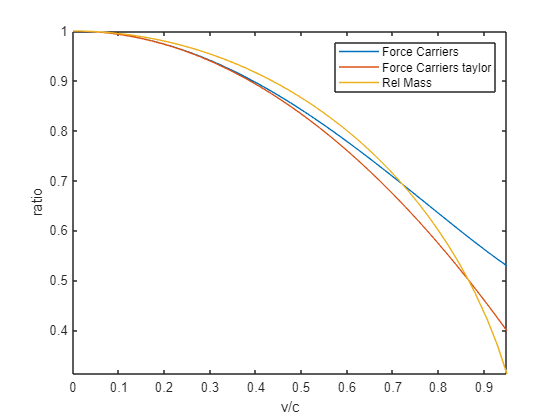

fplot(relEq,plotrange)
xlabel('v/c') 
ylabel('ratio') 
legend({'Force Carriers','Force Carriers taylor',"Rel Mass"},'Location','northeast')
hold off

syms d v r real positive;
assume(d>0)
assume(r>0)
assume(v>0)